clear
clf
load('scan_data.mat');

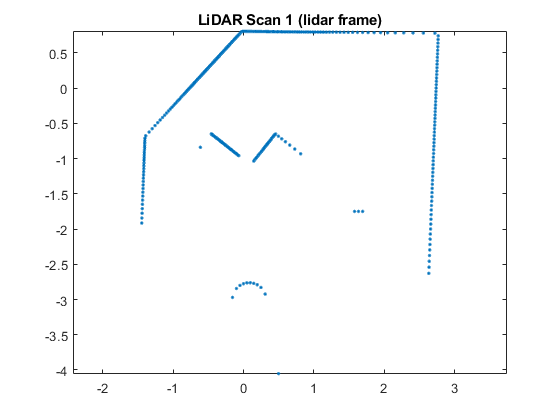

[x1, y1] = pol2cart(theta_1, r_1);
scan1 = [x1 y1 ones(size(x1))];
plot(x1, y1, '.')
axis equal
title('LiDAR Scan 1 (lidar frame)')


pos1 = [0 0];
theta1 = atan2(0, 1);

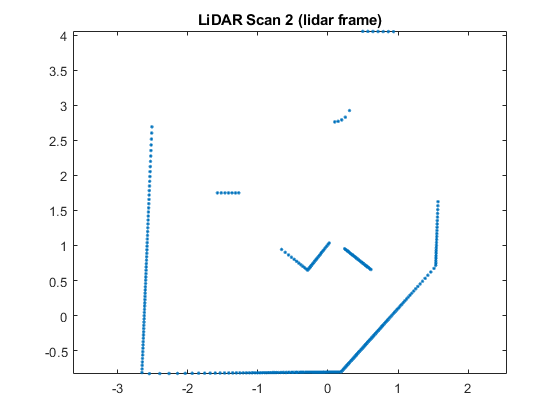

[x2, y2] = pol2cart(theta_2, r_2);
scan2 = [x2 y2 ones(size(x2))];
plot(x2, y2, '.')
axis equal
title('LiDAR Scan 2 (lidar frame)')


pos2 = [0 0];
theta2 = atan2(0, -1);

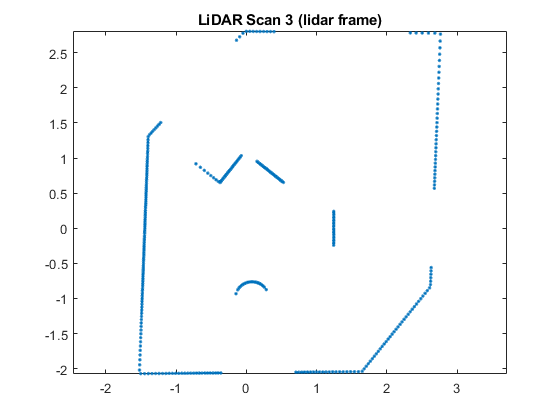

[x3, y3] = pol2cart(theta_3, r_3);
scan3 = [x3 y3 ones(size(x3))];
plot(x3, y3, '.')
axis equal
title('LiDAR Scan 3 (lidar frame)')


pos3 = [0 -2];
theta3 = atan2(0, 1);

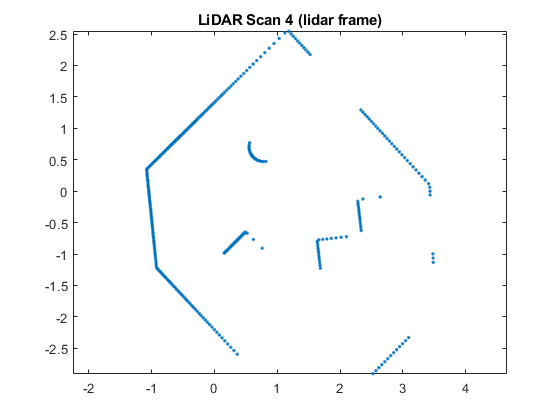

[x4, y4] = pol2cart(theta_4, r_4);
scan4 = [x4 y4 ones(size(x4))];
plot(x4, y4, '.')
axis equal
title('LiDAR Scan 4 (lidar frame)')


pos4 = [1 -3];
theta4 = atan2(1, -1);

Translate to robot frame (translate -0.084 ihat_N)

t_NL = [
    1 0 -0.084;
    0 1 0;
    0 0 1;
];

% transfer scans to the N frame
scan1_N = t_NL * scan1';
scan2_N = t_NL * scan2';
scan3_N = t_NL * scan3';
scan4_N = t_NL * scan4';

translate to fixed global frame

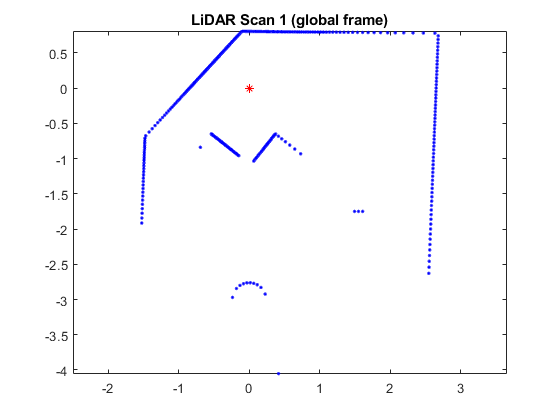

% scan 1
t_GN1 = [
    1 0 pos1(1);
    0 1 pos1(2);
    0 0 1;
];

r_GN1 = [
    cos(theta1) -sin(theta1) 0;
    sin(theta1) cos(theta1) 0;
    0 0 1;
];

scan1_G = t_GN1 * r_GN1 * scan1_N;

plot(scan1_G(1, :), scan1_G(2, :), 'b.', pos1(1), pos1(2), 'r*')
axis equal
title('LiDAR Scan 1 (global frame)')

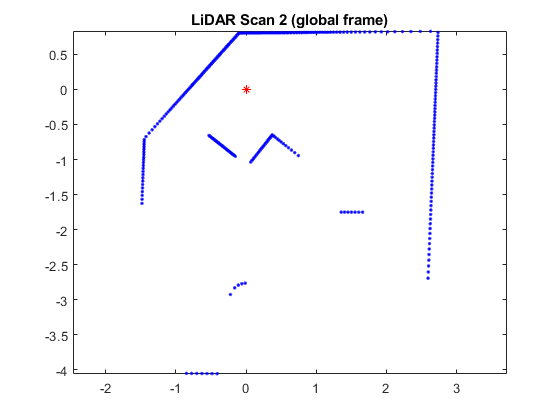

% scan 2
t_GN2 = [
    1 0 pos2(1);
    0 1 pos2(2);
    0 0 1;
];

r_GN2 = [
    cos(theta2) -sin(theta2) 0;
    sin(theta2) cos(theta2) 0;
    0 0 1;
];

scan2_G = t_GN2 * r_GN2 * scan2_N;

plot(scan2_G(1, :), scan2_G(2, :), 'b.', pos2(1), pos2(2), 'r*')
axis equal
title('LiDAR Scan 2 (global frame)')

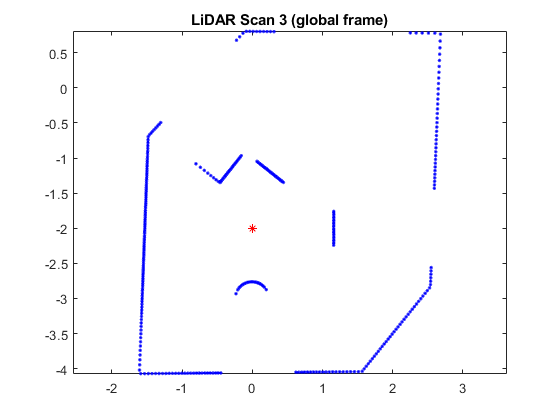

% scan 3
t_GN3 = [
    1 0 pos3(1);
    0 1 pos3(2);
    0 0 1;
];

r_GN3 = [
    cos(theta3) -sin(theta3) 0;
    sin(theta3) cos(theta3) 0;
    0 0 1;
];

scan3_G = t_GN3 * r_GN3 * scan3_N;

plot(scan3_G(1, :), scan3_G(2, :), 'b.', pos3(1), pos3(2), 'r*')
axis equal
title('LiDAR Scan 3 (global frame)')

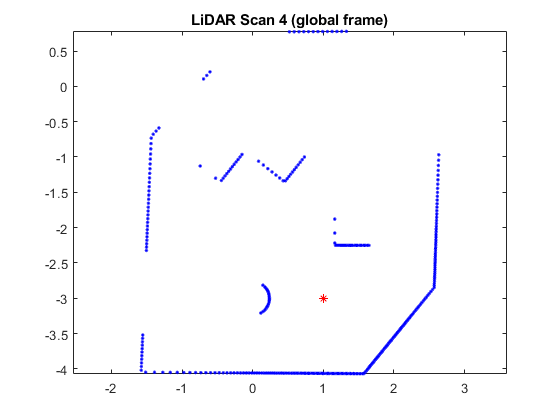

% scan 3
t_GN4 = [
    1 0 pos4(1);
    0 1 pos4(2);
    0 0 1;
];

r_GN4 = [
    cos(theta4) -sin(theta4) 0;
    sin(theta4) cos(theta4) 0;
    0 0 1;
];

scan4_G = t_GN4 * r_GN4 * scan4_N;

plot(scan4_G(1, :), scan4_G(2, :), 'b.', pos4(1), pos4(2), 'r*')
axis equal
title('LiDAR Scan 4 (global frame)')

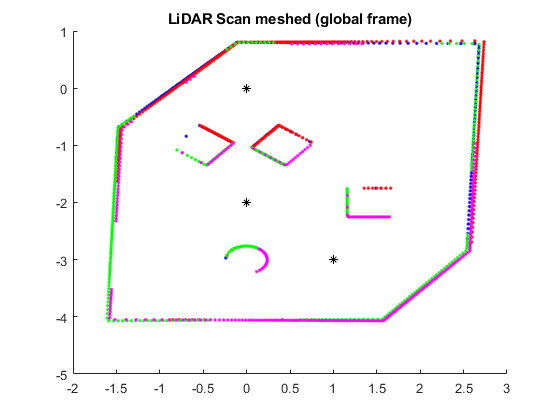

% plot all 4 together
clf
hold on
plot(scan1_G(1, :), scan1_G(2, :), 'b.', pos1(1), pos1(2), 'k*')
plot(scan2_G(1, :), scan2_G(2, :), 'r.', pos2(1), pos2(2), 'k*')
plot(scan3_G(1, :), scan3_G(2, :), 'g.', pos3(1), pos3(2), 'k*')
plot(scan4_G(1, :), scan4_G(2, :), 'm.', pos4(1), pos4(2), 'k*')
title('LiDAR Scan meshed (global frame)')
hold off